x=1:8;%changed item
Mean=[mean(data_c,1);mean(data_p_f,1);mean(data_p_s,1)]';
h = bar(x,Mean,0.6);
f = @(a)bsxfun(@plus,cat(1,a{:,1}),cat(1,a{:,2})).';%获取每一个柱状图中线的x坐标
x_kedu=f(get(h,{'xoffset','xdata'}));


line([x_kedu(3,1),x_kedu(3,1)],[Mean(3,1),...
    Mean(3,2)+(Mean(3,2)-Mean(3,1))/5]);%画连接线。
line([x_kedu(3,2),x_kedu(3,2)],[Mean(3,2),...
    Mean(3,2)+(Mean(3,2)-Mean(3,1))/5]);%画连接线。
line([x_kedu(3,1),x_kedu(3,2)],[Mean(3,2)+(Mean(3,2)-Mean(3,1))/5,...
    Mean(3,2)+(Mean(3,2)-Mean(3,1))/5]);%画连接线
    
  %%
    
     


ax = gca;
ax.XTickLabels = {'左前扣带回','左脑岛','左中央后回','左丘脑',...
    '右前扣带回','右脑岛','右中央后回','右丘脑'};
set(ax,'Fontsize',20);%设置ax标尺大小
ax.XTickLabelRotation = 45;
ax.YLim=[-0.8 2];%设置y轴范围
title('颈型颈椎病患者与对照组痛觉相关脑区的自发神经活动（ALFF）',...
                     'Fontsize',20,'FontWeight','bold');
xlabel('脑区','Fontsize',20,'FontWeight','bold');
ylabel('均数','Fontsize',20,'FontWeight','bold');
h=legend('对照组','颈型颈椎病患者(治疗前)','颈型颈椎病患者(治疗后)');%根据需要修改
h.Location='northwest';
gca1=gtext('**','Fontsize',30);%在都有统计学差异的柱状图上面画双星号。
gtext('*','Fontsize',30);%在治疗前对比中有统计学差异的柱状图上面画单星号。
gtext('*','Fontsize',30);%在治疗前对比中有统计学差异的柱状图上面画单星号。
gtext('*','Fontsize',30);%在治疗前对比中有统计学差异的柱状图上面画单星号。

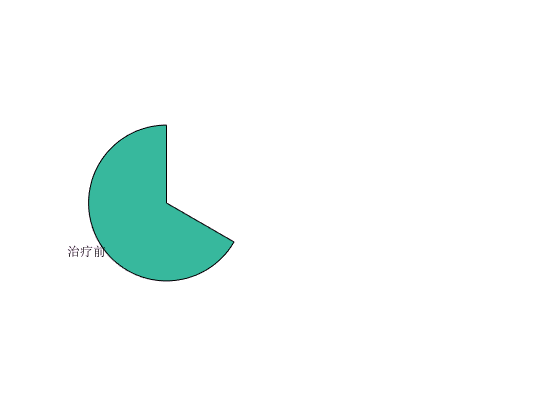

%画饼图，但是本饼图不适宜，因为大于百分之百，可能用
mc=mean(data_c(:,3));
mpf=mean(data_p_f(:,3));
mps=mean(data_p_s(:,3));
perc1=(mpf-mc)/mc;%治疗前，病人中央后回神经活动的绝对值较对照组增加的百分比
perc2=(mps-mc)/mc;%治疗后，病人中央后回神经活动的绝对值较对照组增加的百分比
ax1 = subplot(1,2,1);
i=perc1*100;i=round(i);%保留2位小数
label1 = {'',['治疗前(',num2str(i),'%)']};
p1=pie(ax1,[1-perc1,perc1],label1);

t = p1(2);

未定义与 'double' 类型的输入参数相对应的函数 'p'。

t.FontSize = 30;%设置label大小
% colormap([0,0,1]);%颜色
ax2 = subplot(1,2,2);
i=perc2*100;i=round(i);%保留2位小数
label2 = {'',['治疗后(',num2str(i),'%)']};
p2=pie(ax2,[1-perc2,perc2],label2);
t = p2(2);
t.FontSize = 30;%设置label大小
% colormap([0,0,1])%颜色
fig=suptitle('治疗前后正常与异常自发脑活动的比值变化');
set(fig,'Fontsize',40,'FontWeight','bold');